clear all
nu = 8e4;
c = 335; %Скорость звука
lambda_s = c/nu;
optimal_d = 0.95*c/(2*nu); %Рассчёт оптимального расстояния между датчиками (коэффициент должен лежать в пределах от 0 до 1)
xn = [-3*optimal_d, -2*optimal_d, 0, optimal_d, 2*optimal_d, 3*optimal_d]; %Координаты микрофонов в МН с неэквидистантным расположением датчиков
theta_zero = 50; %Угол, с которого приходит сигнал

phi_limits = [1,180]; %Границы ДН по азимутальному углу в градусах [от,до]
theta = linspace(1,phi_limits(2),phi_limits(2));

Построим границу Крамера-Рао (CRB или CRLB) (для линейного массива)

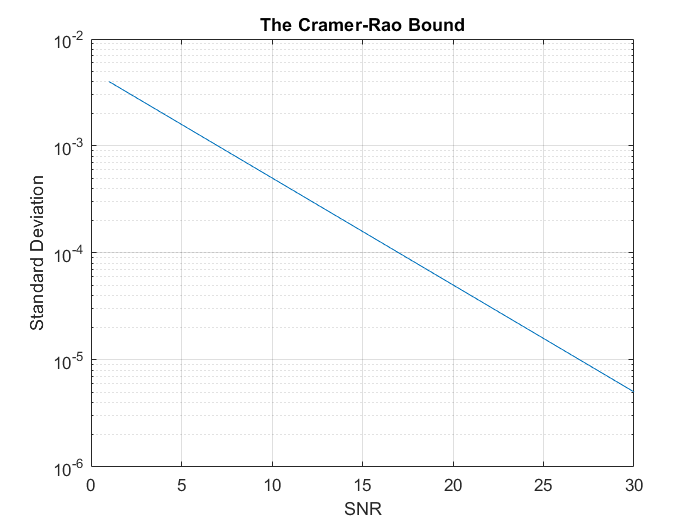

d_mean = sum(xn.^2);
K = 1; %Количество кадров (наблюдений)
SNR_db = 1:30;
SNR = 10.^(SNR_db/10);
CRB = (lambda_s^2)./(8*pi^2*K*SNR*(cosd(theta(theta_zero))^2)*d_mean); %Формула для линейного массива
figure(1);
semilogy(SNR_db,CRB);
title("The Cramer-Rao Bound");
xlabel("SNR");
ylabel("Standard Deviation");
grid on;